# Examples for using the `planet3D` and `background` functions.

Copyright © 2021 Tamas Kis

Add path to "planet3D":

addpath('planet3D');

## Example #1: Celestial bodies with the Milky Way in the background.

Initialize the figure.

figure;

Choose which planet to plot. For this example, we choose Mars.

planet = 'Mars';

Produce the plot.

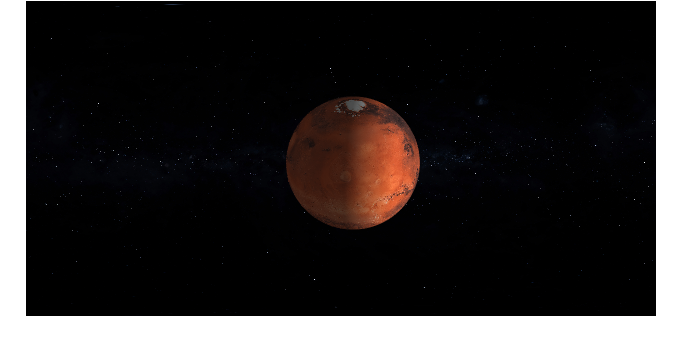

figure;
background('Milky Way');
planet3D(planet);
light('Position',[1,-1,0]);

## Example #2: Plot Saturn with respect to the ecliptic plane on white background with grid lines.

Set the reference plane to the ecliptic plane.

opts_example2.RefPlane = 'ecliptic';

Create the figure.

figure;
planet3D('Saturn',opts_example2);
light('Position',[1,-1,0]);
grid on;

Changes viewpoint.

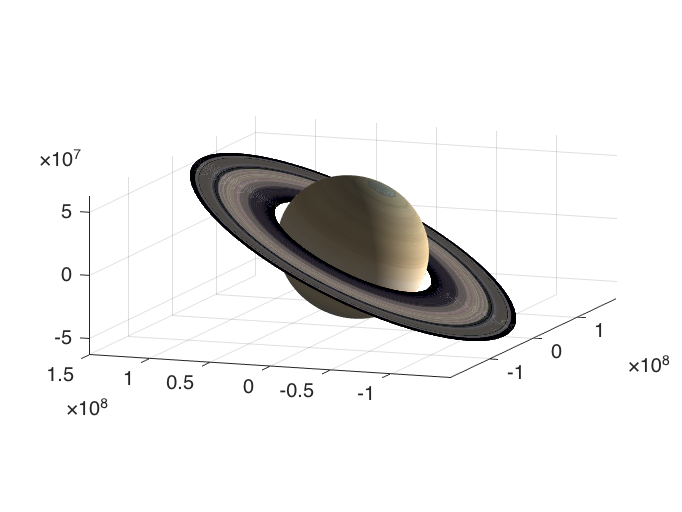

view(-70,10)

## Example #3: Plotting Earth coastlines with respect to ecliptic plane on white background with grid lines. Earth is also rotated about its third axis.

Set the reference plane to the ecliptic plane.

opts_example3.RefPlane = 'ecliptic';

Rotates Earth about its 3rd axis by 45 degrees.

opts_example3.RotAngle = 45;

Create the figure.

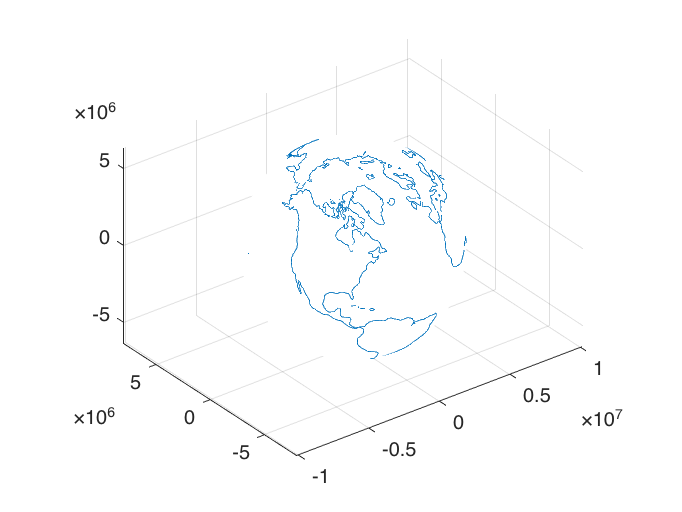

figure;
planet3D('Earth Coastlines',opts_example3);
grid on;

## Example #4: Plot orbit around transparent Earth on black background with grid lines.

First, we load sample orbit data provided with the download.

orbit_data = struct2array(load('sampledata/eccentric_keplerian_orbit.mat'));

Extracting the ECI position vector,

r_eci = orbit_data.r_eci;

Extracting the individual components,

rI = r_eci(1,:);
rJ = r_eci(2,:);
rK = r_eci(3,:);

We initialize the figure and plot a plain black background.

figure;
background('Black');

Next, to plot the Earth with 75% transparency (corresponding to 25% opacity), we set `FaceAlpha` to 0.25.

opts_example4.FaceAlpha = 0.25;

Plotting the Earth (with clouds) with 75% transparency together with the orbit,

hold on;
planet3D('Earth Cloudy',opts_example4);
plot3(rI,rJ,rK,'Color',[0.5490,0.0824,0.0824],'LineWidth',1.5);
hold off;

To plot a grid on the black background, we set the grid lines to white and change their transparency to 75% transparency (i.e. 25% opacity).

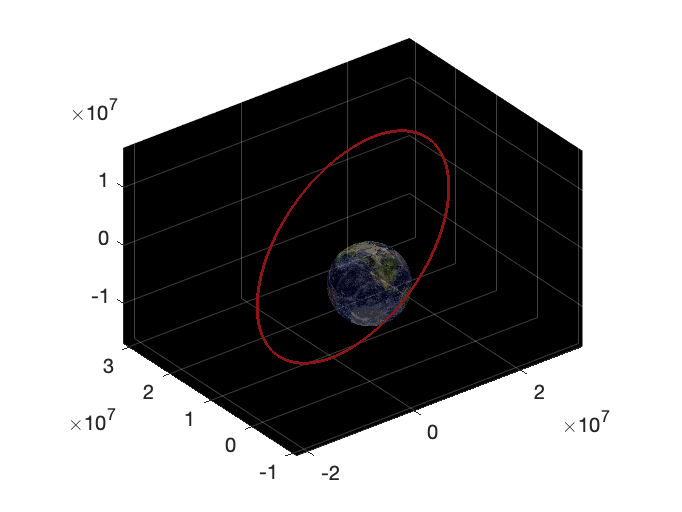

% turn grid on
grid on;

% get axis handle
ax = gca;

% set grid lines to white
ax.GridColor = [1,1,1];

% set grid lines to 75% transparency (25% opacity)
ax.GridAlpha = 0.25;